# cwEDMR on Pin SC using Elexsys

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% File and Run options
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210628';
Opt.Ldir0 = dir([Opt.LFolder, '\*_0Deg.DTA']);
Opt.LPaths = [Opt.LFolder, '\', Opt.Ldir0.name];
Opt.Ldir90 = dir([Opt.LFolder, '\*_90Deg.DTA']);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

% Field offset (obtained from 013_calibration_NC60)
B0Offset = 1.763;
Idc = [256 294 217 148]; % uA
cw = struct();
idxStart = 9;
ncw = numel(Opt.Ldir0) - idxStart + 1;
for icw = 1:ncw
    iDir = idxStart + icw - 1;
    LPath0_ = [Opt.LFolder, '\', Opt.Ldir0(iDir).name];
    LPath90_ = [Opt.LFolder, '\', Opt.Ldir90(iDir).name];

    [cw(icw).xRaw, cw(icw).yRaw, cw(icw).Params] = ...
        eprloadQuad(LPath0_, LPath90_);
    
    cw(icw).x = (cw(icw).xRaw - B0Offset)/10; % mT
    newStr = strsplit(Opt.Ldir0(iDir).name, '_');
    cw(icw).Title = [strrep(newStr{2}, 'p', '.'), ' ', num2str(Idc(icw)), 'uA'];
end
% Reordering
cw(5) = cw(1); cw(1) = cw(4); cw(4) = cw(2); cw(2) = cw(3); cw(3) = cw(5);
cw(5) = [];

#### Baseline correction

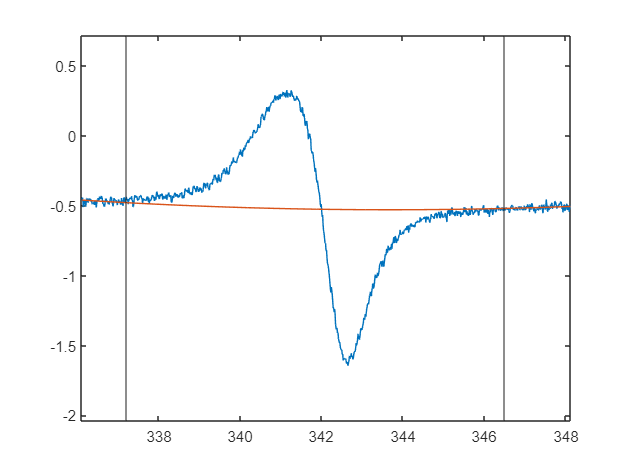

Opt.Bl.Order = 2;
Opt.Bl.Range = [336.1 337.2; 346.5 348];

icw = 4;
cw(icw).BlOpt = Opt.Bl;
% y1 is the spectrum baseline corrected but not phase corrected
[cw(icw).y1, cw(icw).Bl] = ...
    subtractBaseline(cw(icw).x, cw(icw).yRaw, Opt.Bl);

figure()
plot(cw(icw).x, real(cw(icw).yRaw), cw(icw).x, real(cw(icw).Bl));
xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).yRaw), 0.2));
xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));

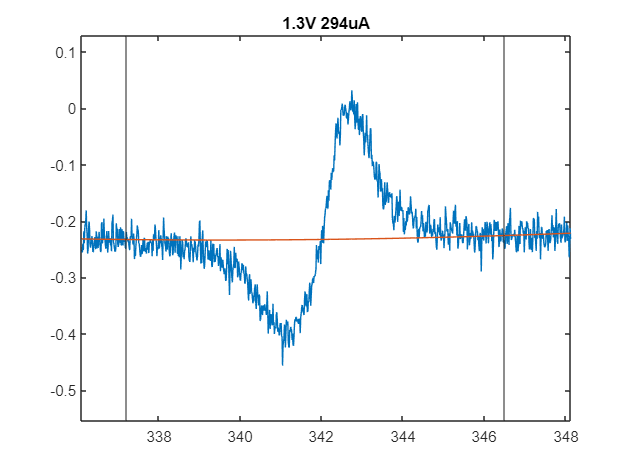

figure()
plot(cw(icw).x, imag(cw(icw).yRaw), cw(icw).x, imag(cw(icw).Bl)); 
xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(imag(cw(icw).yRaw), 0.2));
xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
title(cw(icw).Title)

#### Phase correction

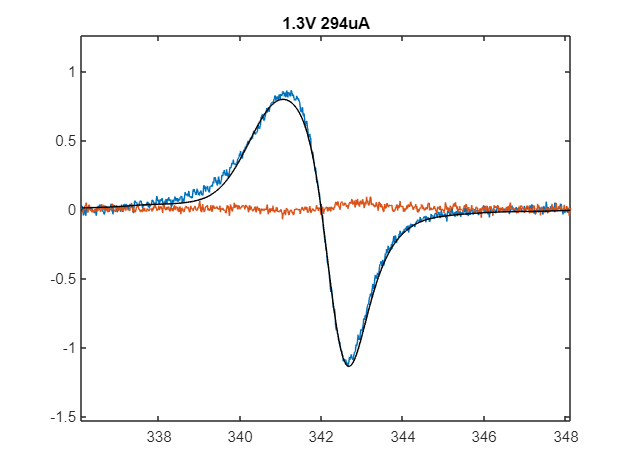

% y2 is the spectrum baseline and phase corrected
[cw(icw).y2, cw(icw).Phase] = correctPhase(cw(icw).y1, 'Maximum');
cw(icw).y = real(cw(icw).y2);

load('D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis\fit_spectrum.mat')
figure();
plot(cw(icw).x, real(cw(icw).y2), cw(icw).x, imag(cw(icw).y2));
hold on
plot(cw(icw).x, Fit1.fit, 'Color', [0 0 0])
xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).y2), 0.2));
title(cw(icw).Title)